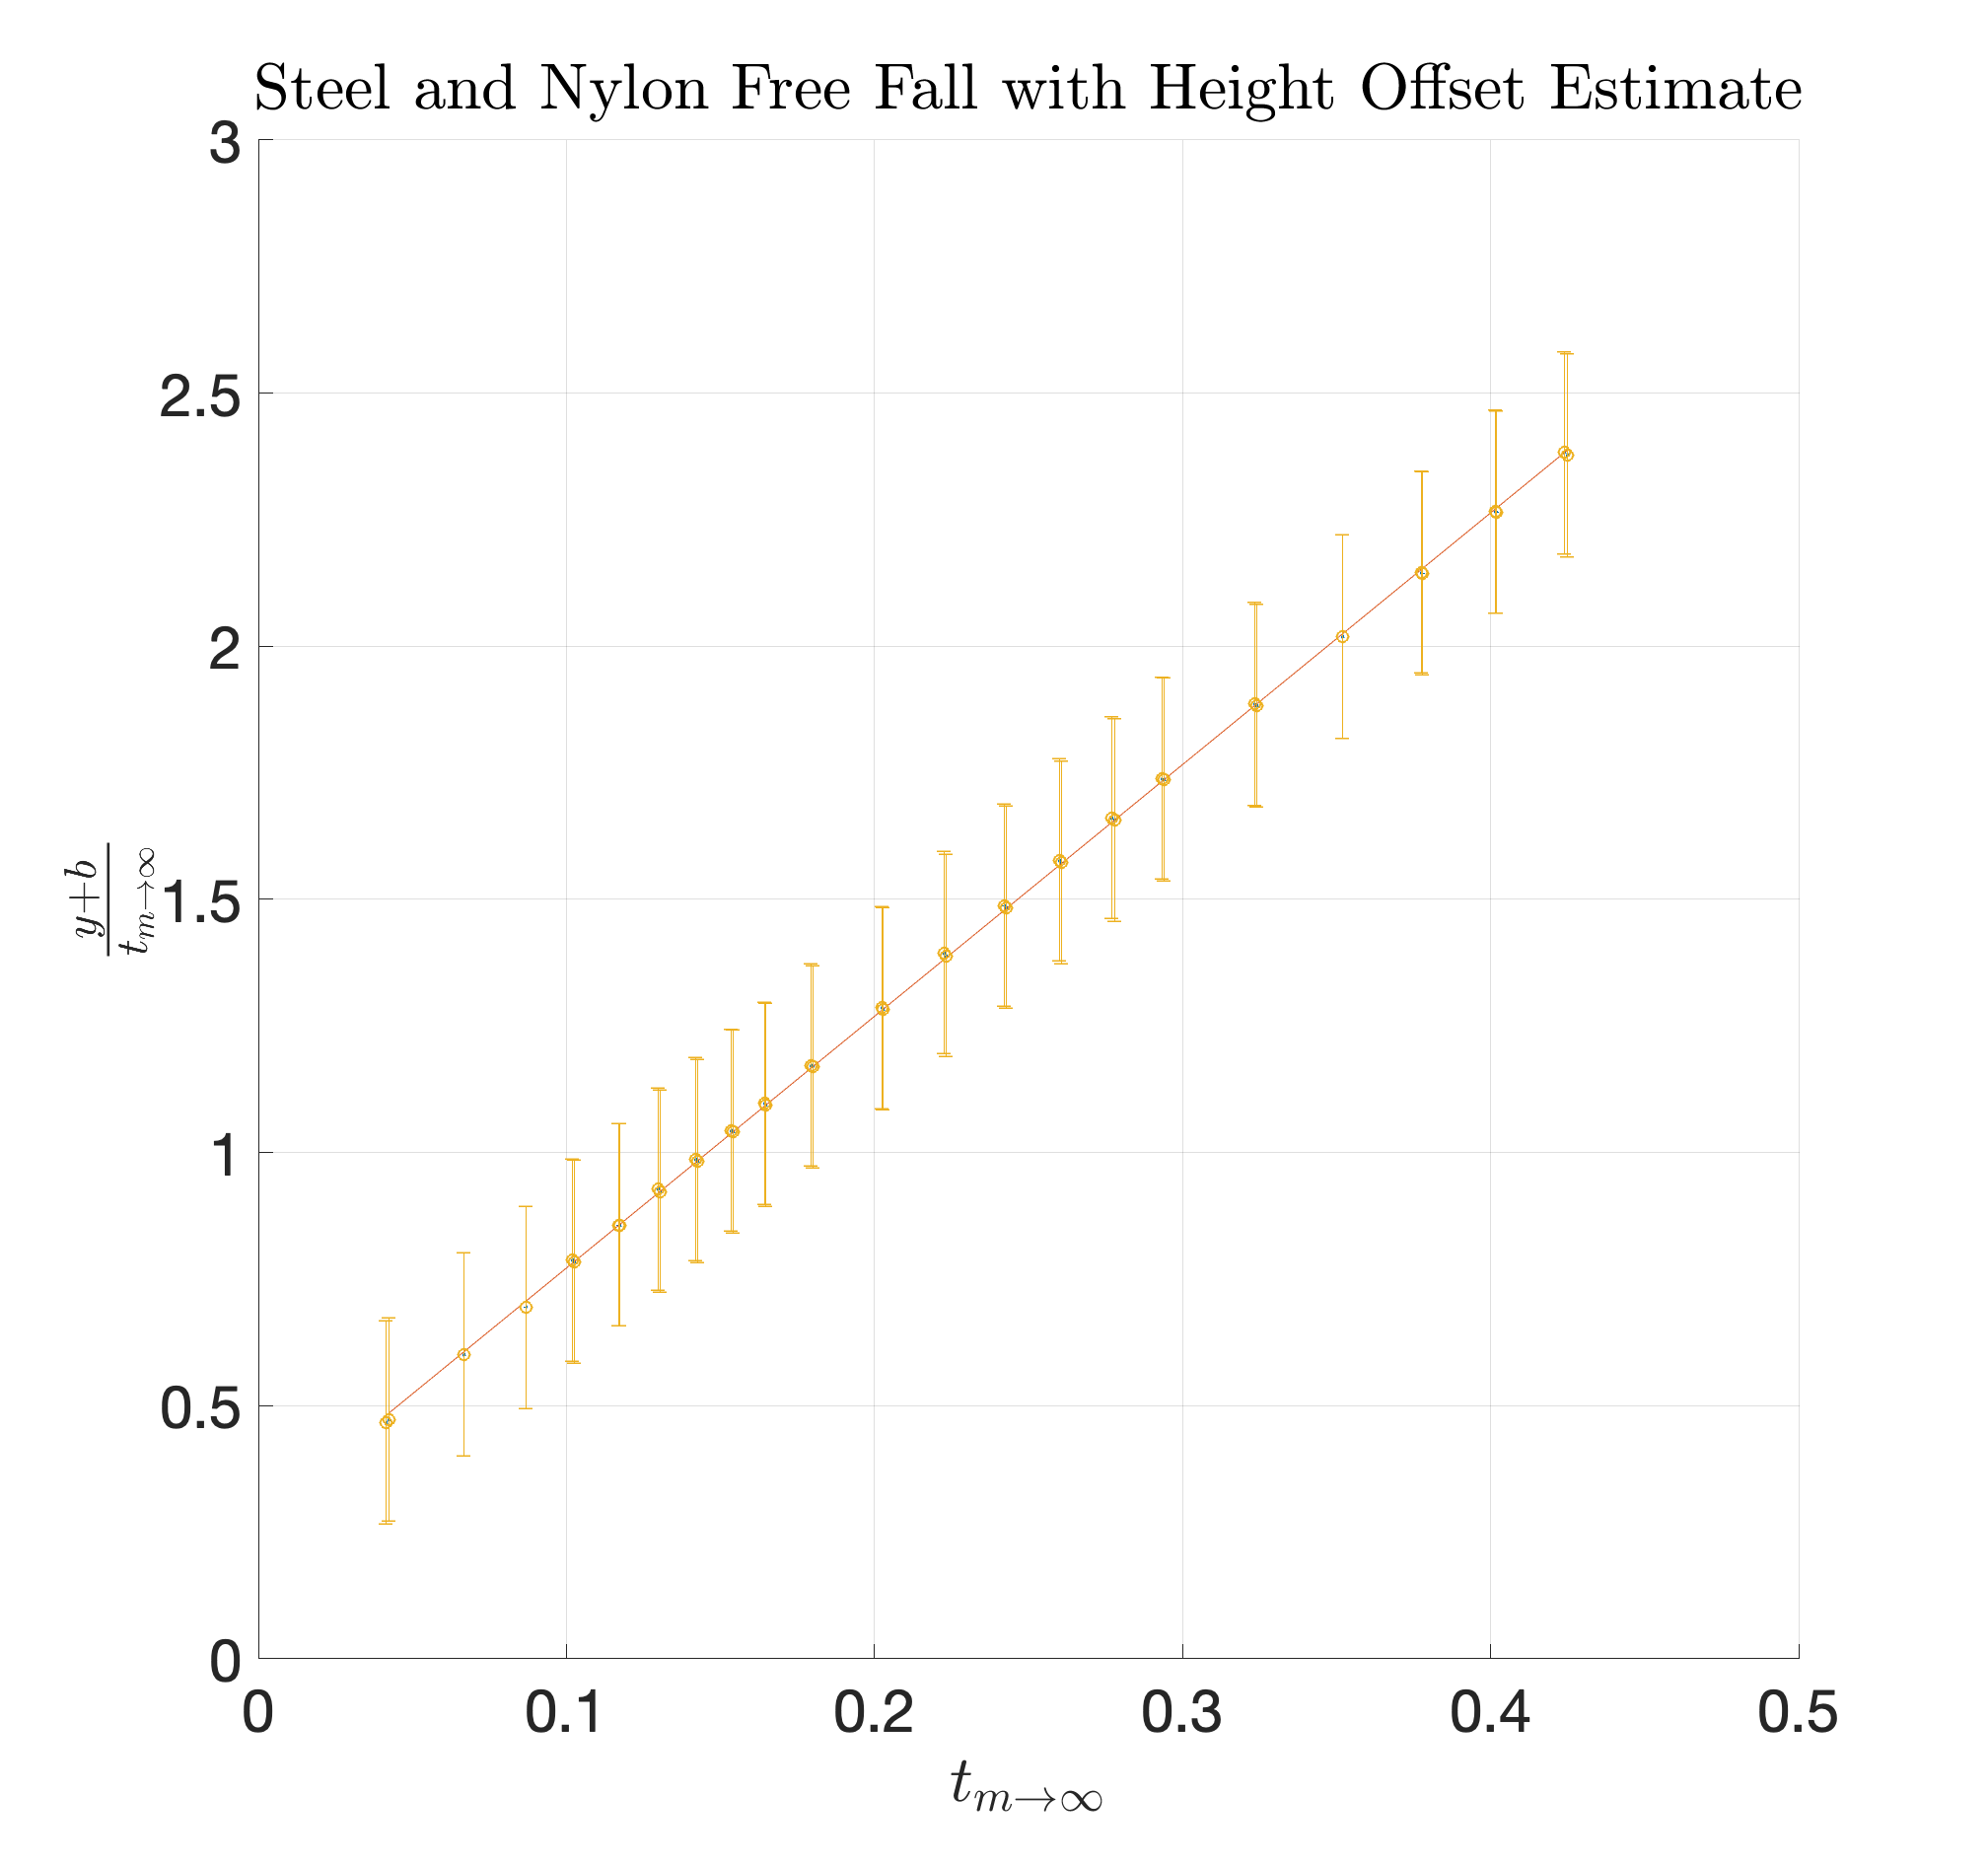

close all
clear all
data = dlmread('Time Measurements.csv',',',1,0);
t_nylon = data(:,1);
t_steel = data(:,2);
t_nylon_err = std(t_nylon);
t_steel_err = std(t_steel);
% t_nylon_err = 10^(-5);
% t_steel_err = 10^(-5);

data = dlmread('Ball Dropper Data.csv',',',2,5);
y = data(:,1)./1000; % drop heights (meters)
y_err = data(:,2)./1000; % meters
t_nylon = data(:,3);% seconds
t_steel = data(:,4);% seconds
m_nylon = 0.00409; % kg
m_steel = 0.02817; % kg

delete = [4,24];
[t_nylon,t_steel,y,y_err] = drop(delete,t_nylon,t_steel,y,y_err);
t_inf = (t_steel*m_steel- t_nylon*m_nylon)./(m_steel-m_nylon);
t_inf_err = 1/(m_steel-...
    m_nylon).*sqrt((m_steel.*t_steel_err).^2+....
    (m_nylon.*t_nylon_err).^2);

%% ESTIMATE OF B
b = 0.01; % m
b_err = 0.002; 
dydt = (y+b)./t_inf;
dydt_err = sqrt(t_inf_err^2.*((y+b)./t_inf.^2).^2+...
                y_err.^2.*(1./t_inf).^2 + ...
                b_err.^2.*(1./b).^2);

%% FIT WITH ESTIMATE OF B         
[fitobj, gof, outp] = fit(t_inf, dydt,'poly1','Weights',(1./dydt_err).^2);
yplot2 = fitobj.p1.*t_inf+fitobj.p2;
figure(1)
set(gcf,'Units','Normalized','Position',[0.35 0.5 0.3 0.5])
scatter(t_inf,dydt,2)
hold on
plot(t_inf,yplot2)
xlabel('$t_{m \rightarrow \infty}$','Interpreter','latex')
ylabel('$\frac{y+b}{t_{m \rightarrow \infty}}$',...
    'Interpreter','latex')
title('Steel and Nylon Free Fall with Height Offset Estimate','Interpreter','latex')
set(gca,'FontSize',30)   
grid on
errorbar(t_inf,dydt,dydt_err,'o');
hold off

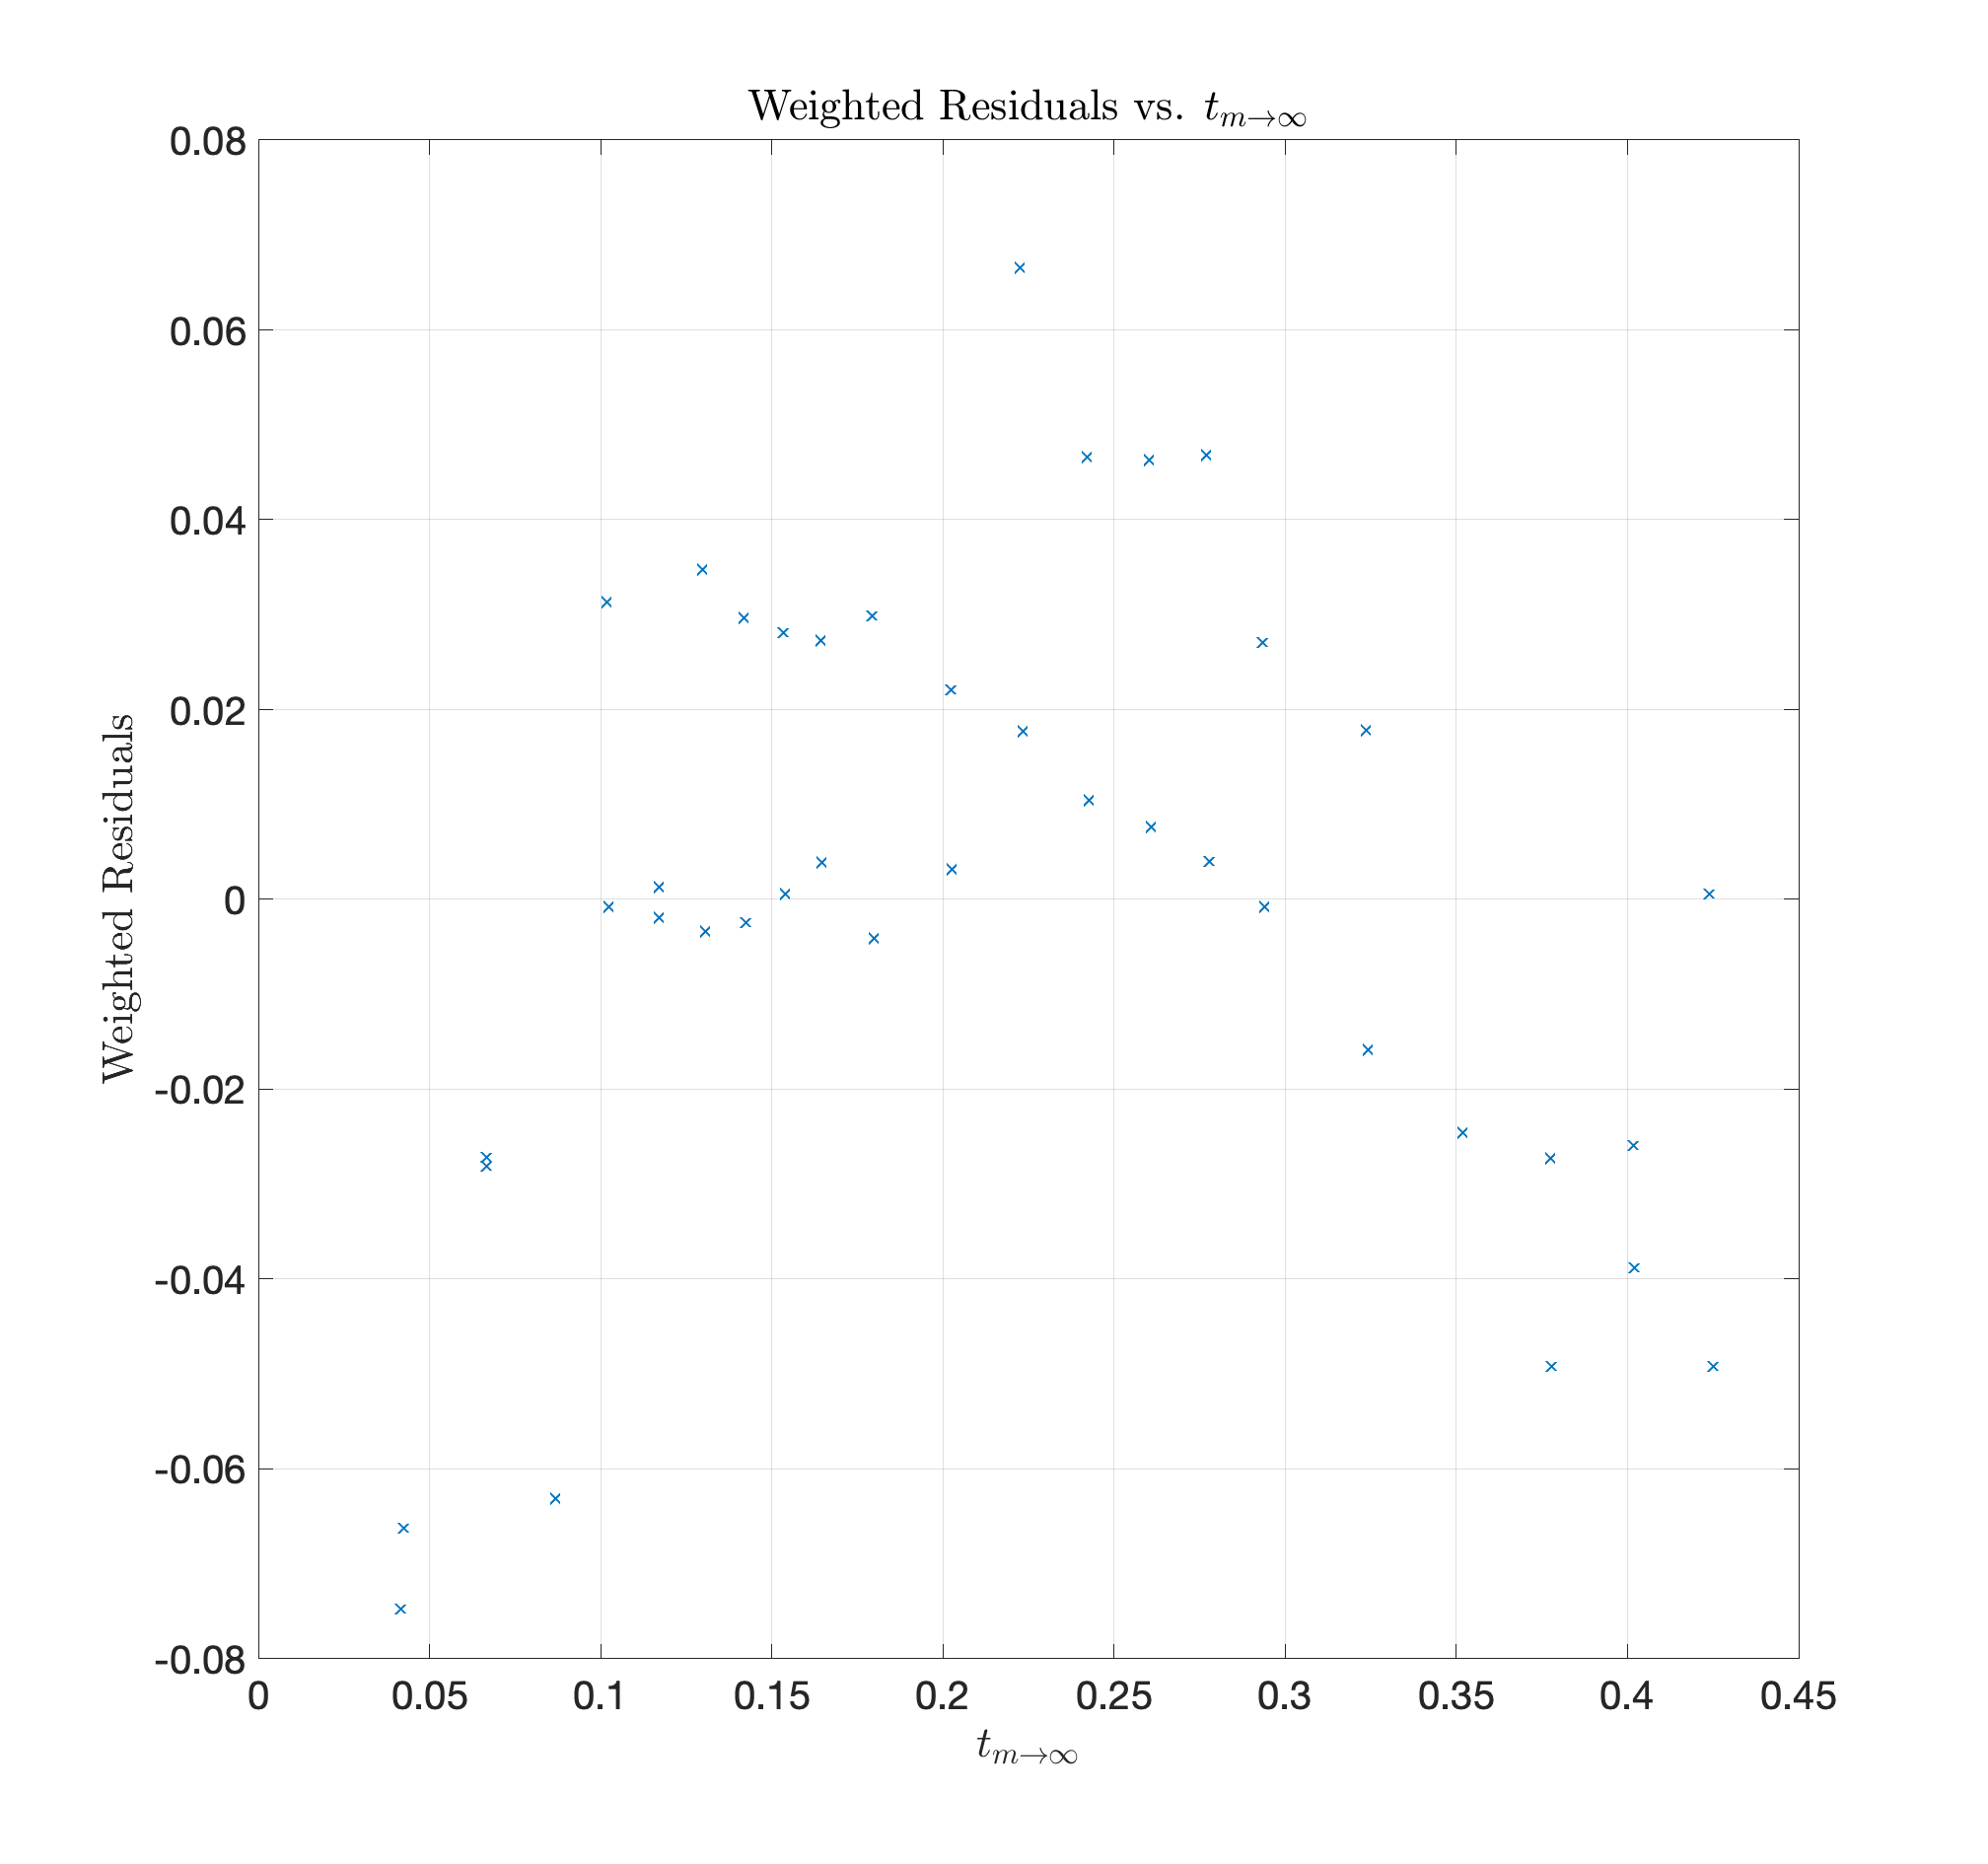

figure(2)
set(gcf,'Units','Normalized','Position',[0.65 0.5 0.3 0.5])
plot(t_inf(1:length(outp.residuals),:), (outp.residuals), 'x')
title('Weighted Residuals vs. $t_{m \rightarrow \infty}$','Interpreter','latex')
xlabel('$t_{m \rightarrow \infty}$','Interpreter','latex')
ylabel('Weighted Residuals','Interpreter','latex')
set(gca,'FontSize',20) 
grid on


%% ITERATE OVER DELTA VALUE FOR BEST B VALUE
del = (-0.01:0.00005:0.013)';
length(del)

ans = 461

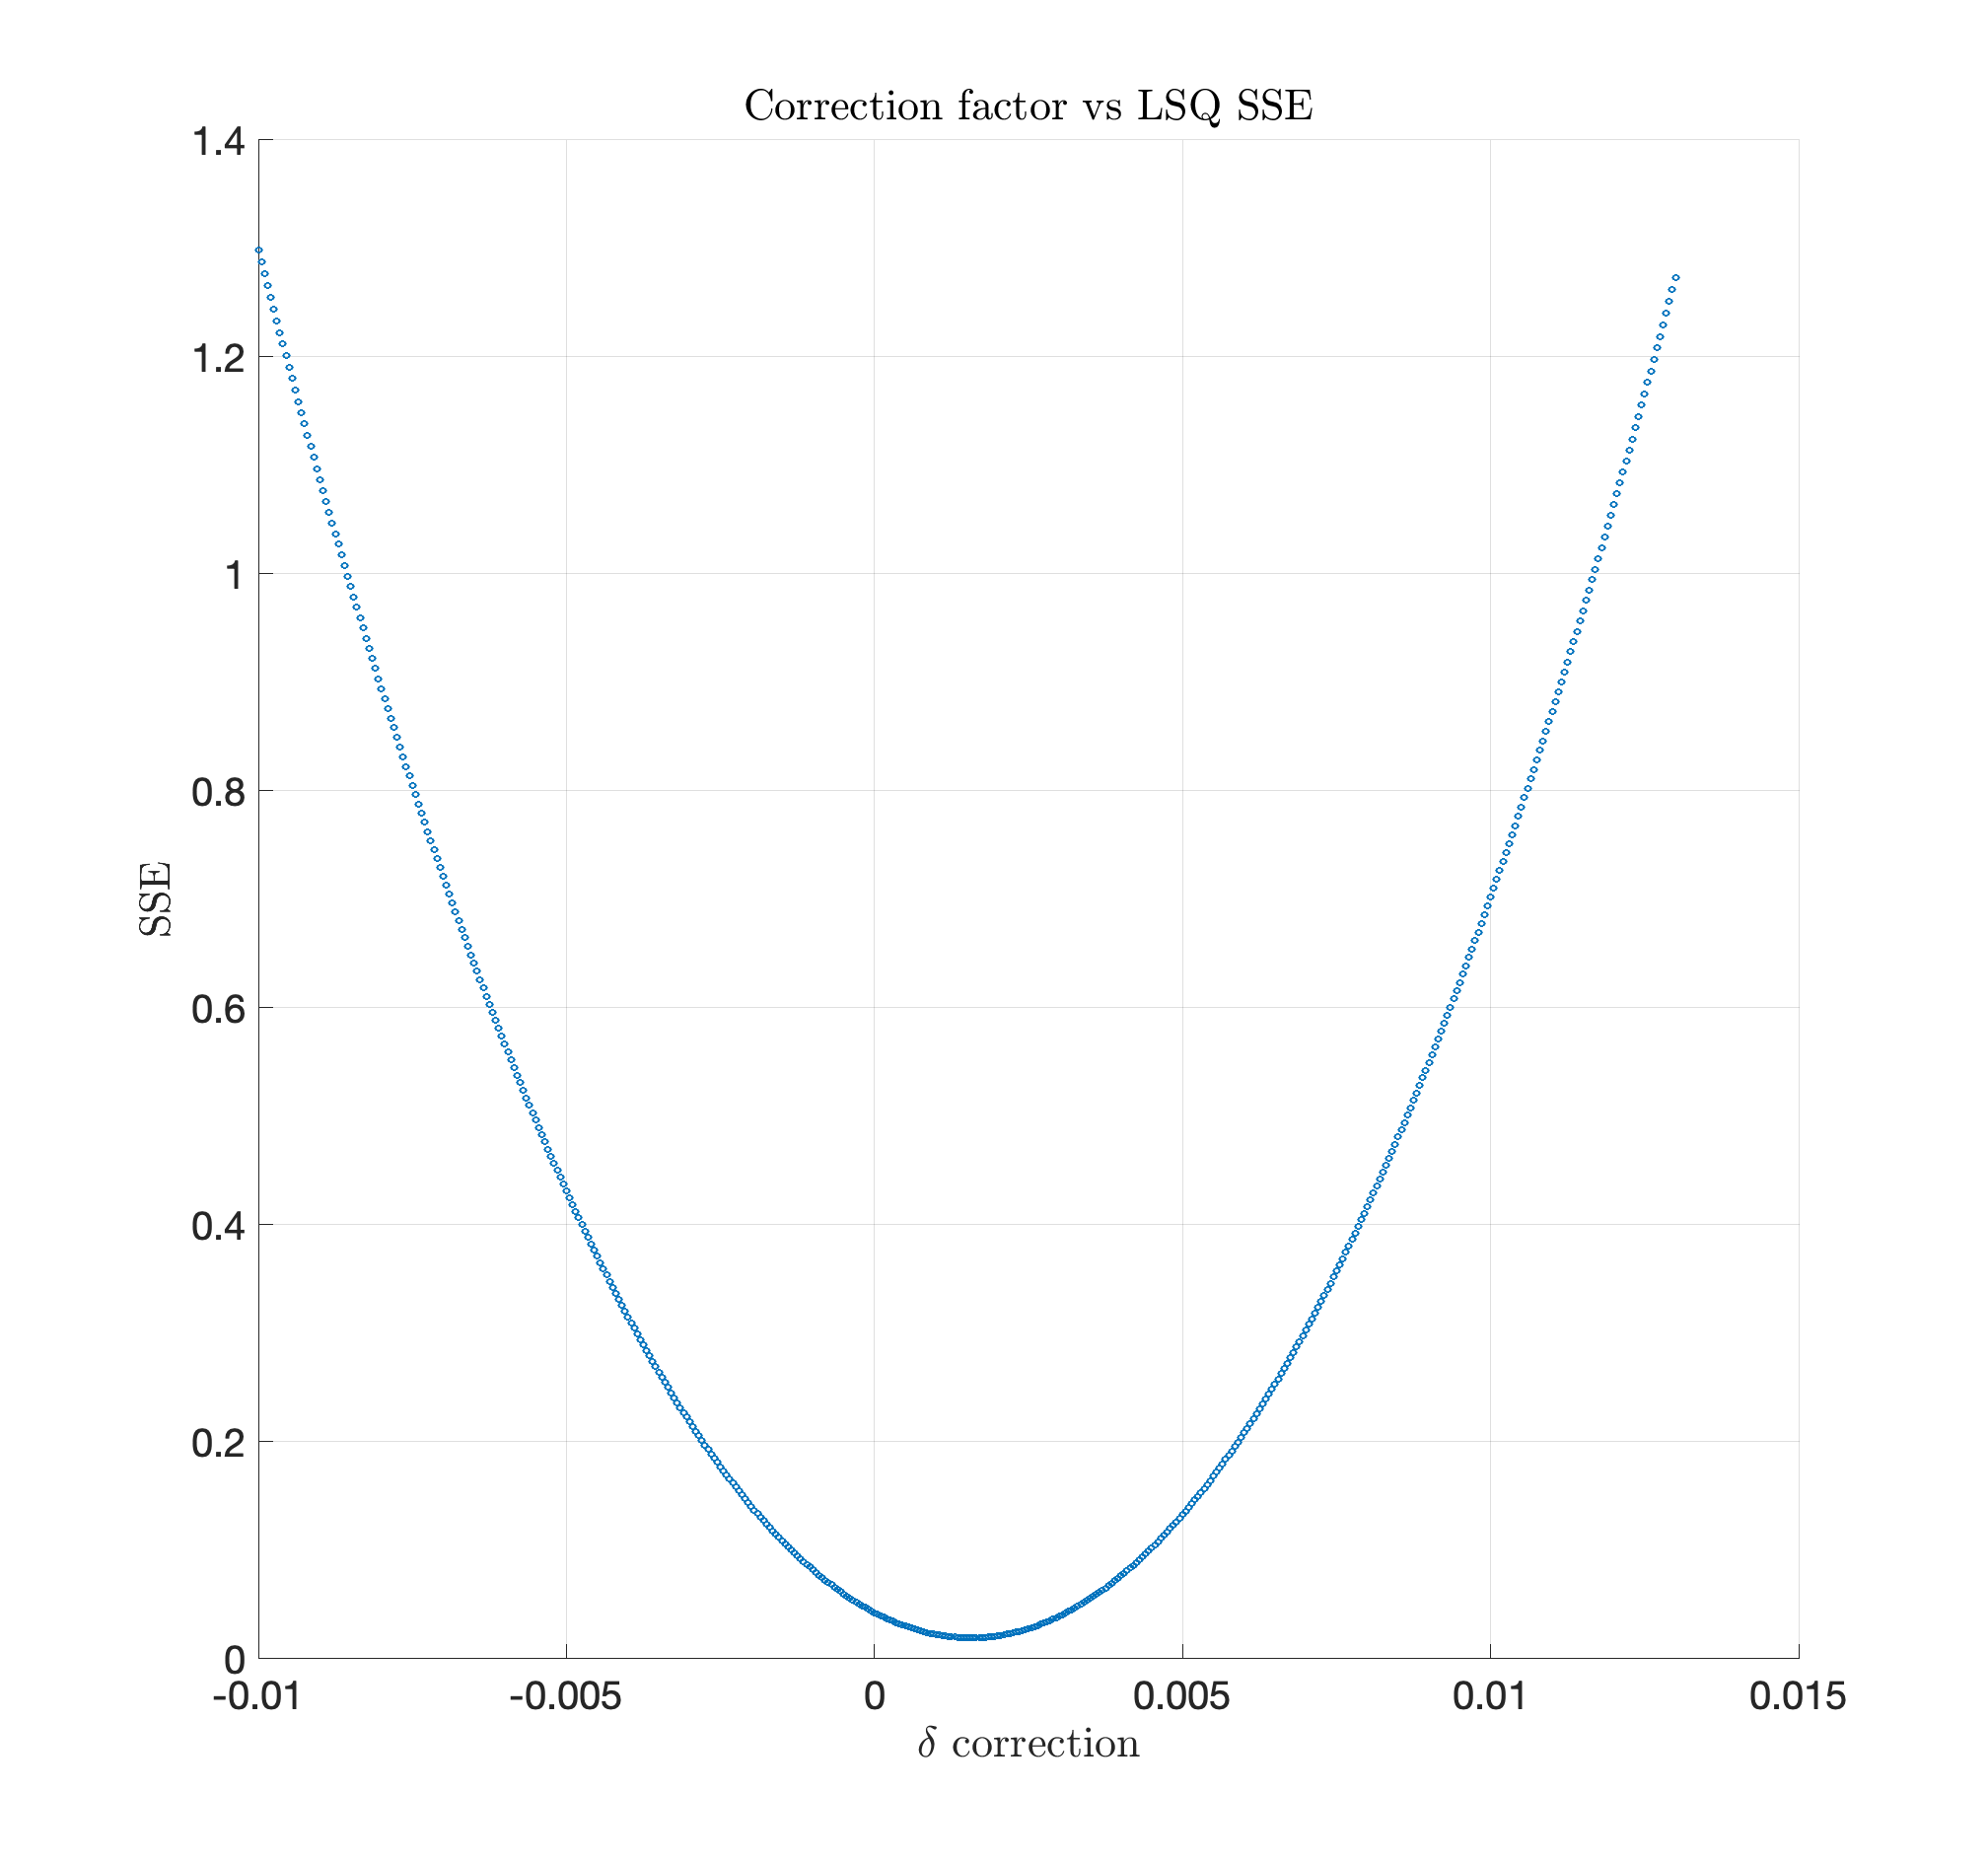

sse = zeros(length(del),1);
for i = 1:length(del)
    del_0 = del(i);
    dydt = (y+b)./t_inf + del_0./t_inf;   
    dydt_err = sqrt(t_inf_err^2.*((y+b)./t_inf.^2).^2+...
                y_err.^2.*(1./t_inf).^2 + ...
                b_err.^2.*(1./b).^2);   
    sse(i) = getSSE(t_inf,dydt,dydt_err,del_0);
    
end
figure(3)
set(gcf,'Units','Normalized','Position',[0.65 0.5 0.3 0.5])
scatter(del,sse,10)
xlabel('$\delta$ correction','Interpreter','latex')
ylabel('SSE','Interpreter','latex')
title('Correction factor vs LSQ SSE','Interpreter','latex')
set(gca,'FontSize',20) 
grid on

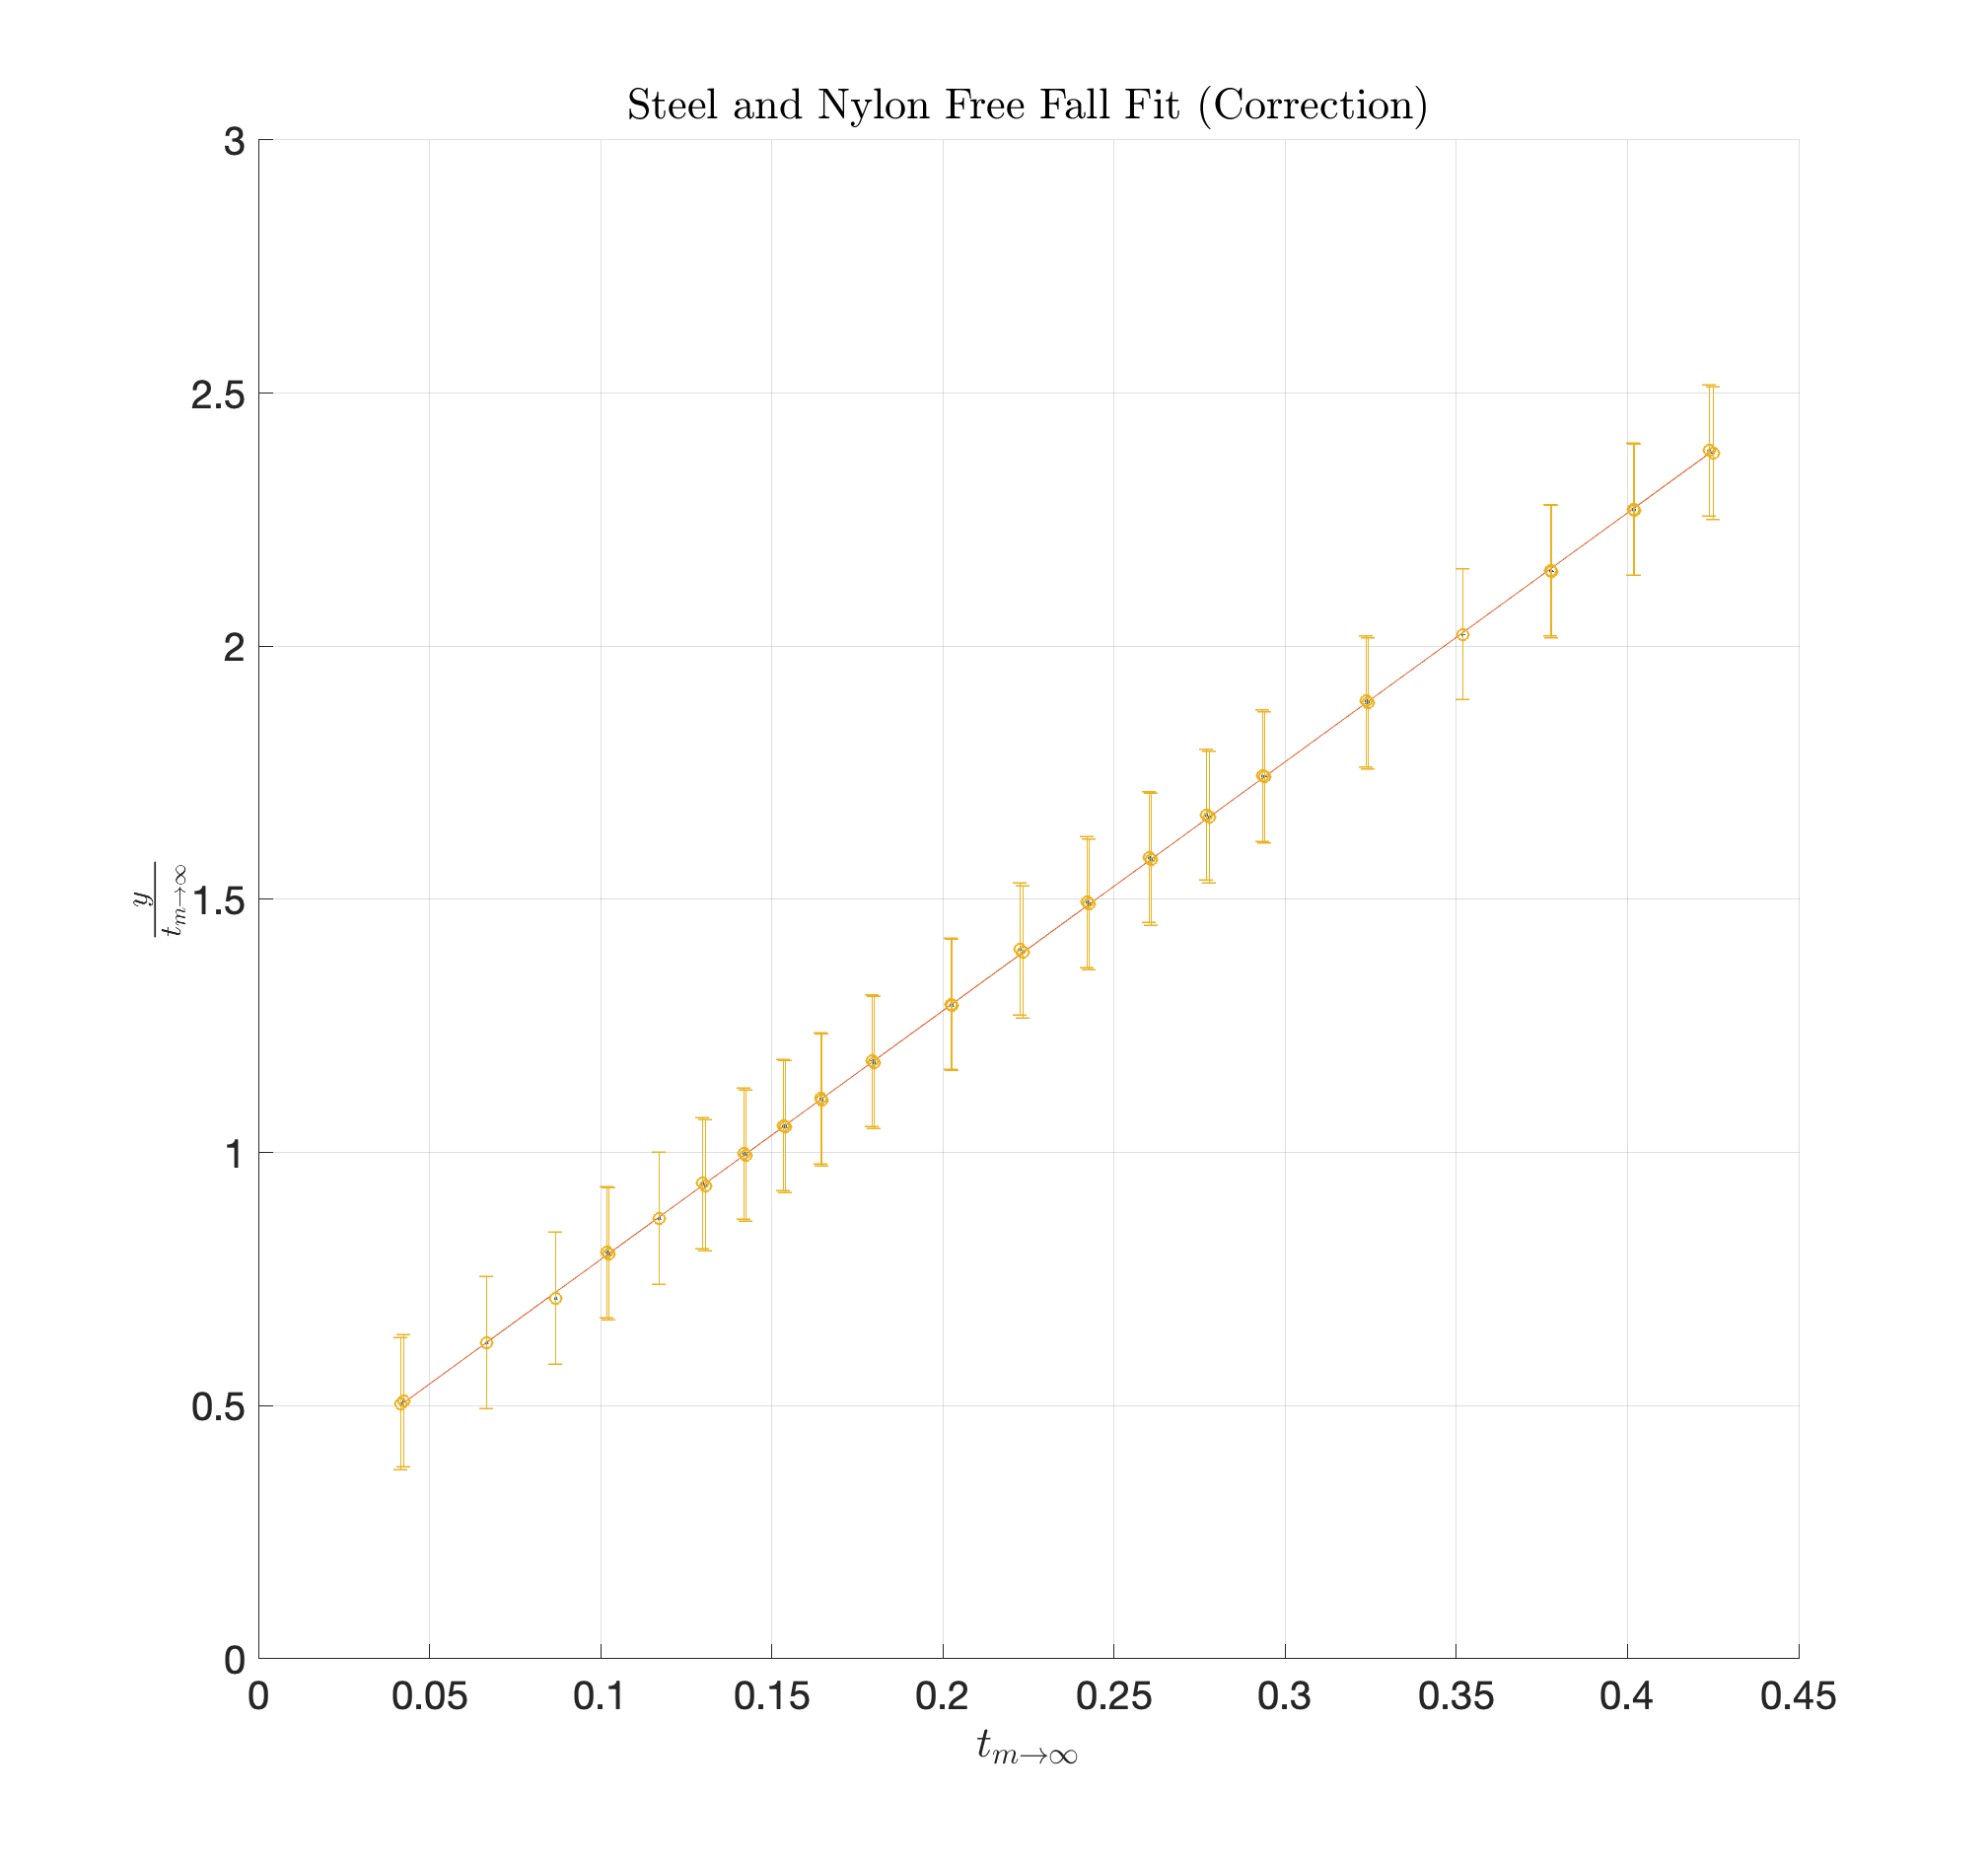


sse = -1.*sse;
[px,py] = findpeaks(sse,del);
del_best = py;

%% FINAL CALCULATION AND FIT
b = b+del_best;
b_err = 1.5*10^-3;
dydt = (y+b)./t_inf ; 
dydt_err = sqrt(t_inf_err^2.*((y+b)./t_inf.^2).^2+...
                y_err.^2.*(1./t_inf).^2 + ...
                b_err.^2.*(1./b).^2);   
            
[fitobj, gof, outp] = fit(t_inf, dydt,'poly1', 'Weights',(1./dydt_err).^2);                
yp = fitobj.p1.*t_inf + fitobj.p2;

figure(4)
set(gcf,'Units','Normalized','Position',[0.5 0.05 0.3 0.5])
scatter(t_inf,dydt,2)
hold on
plot(t_inf,yp)
xlabel('$t_{m \rightarrow \infty}$','Interpreter','latex')
ylabel('$\frac{y}{t_{m \rightarrow \infty}}$',...
    'Interpreter','latex')
title('Steel and Nylon Free Fall Fit (Correction)',...
    'Interpreter','latex')
set(gca,'FontSize',20) 
grid on
errorbar(t_inf,dydt,dydt_err,'o');
hold off

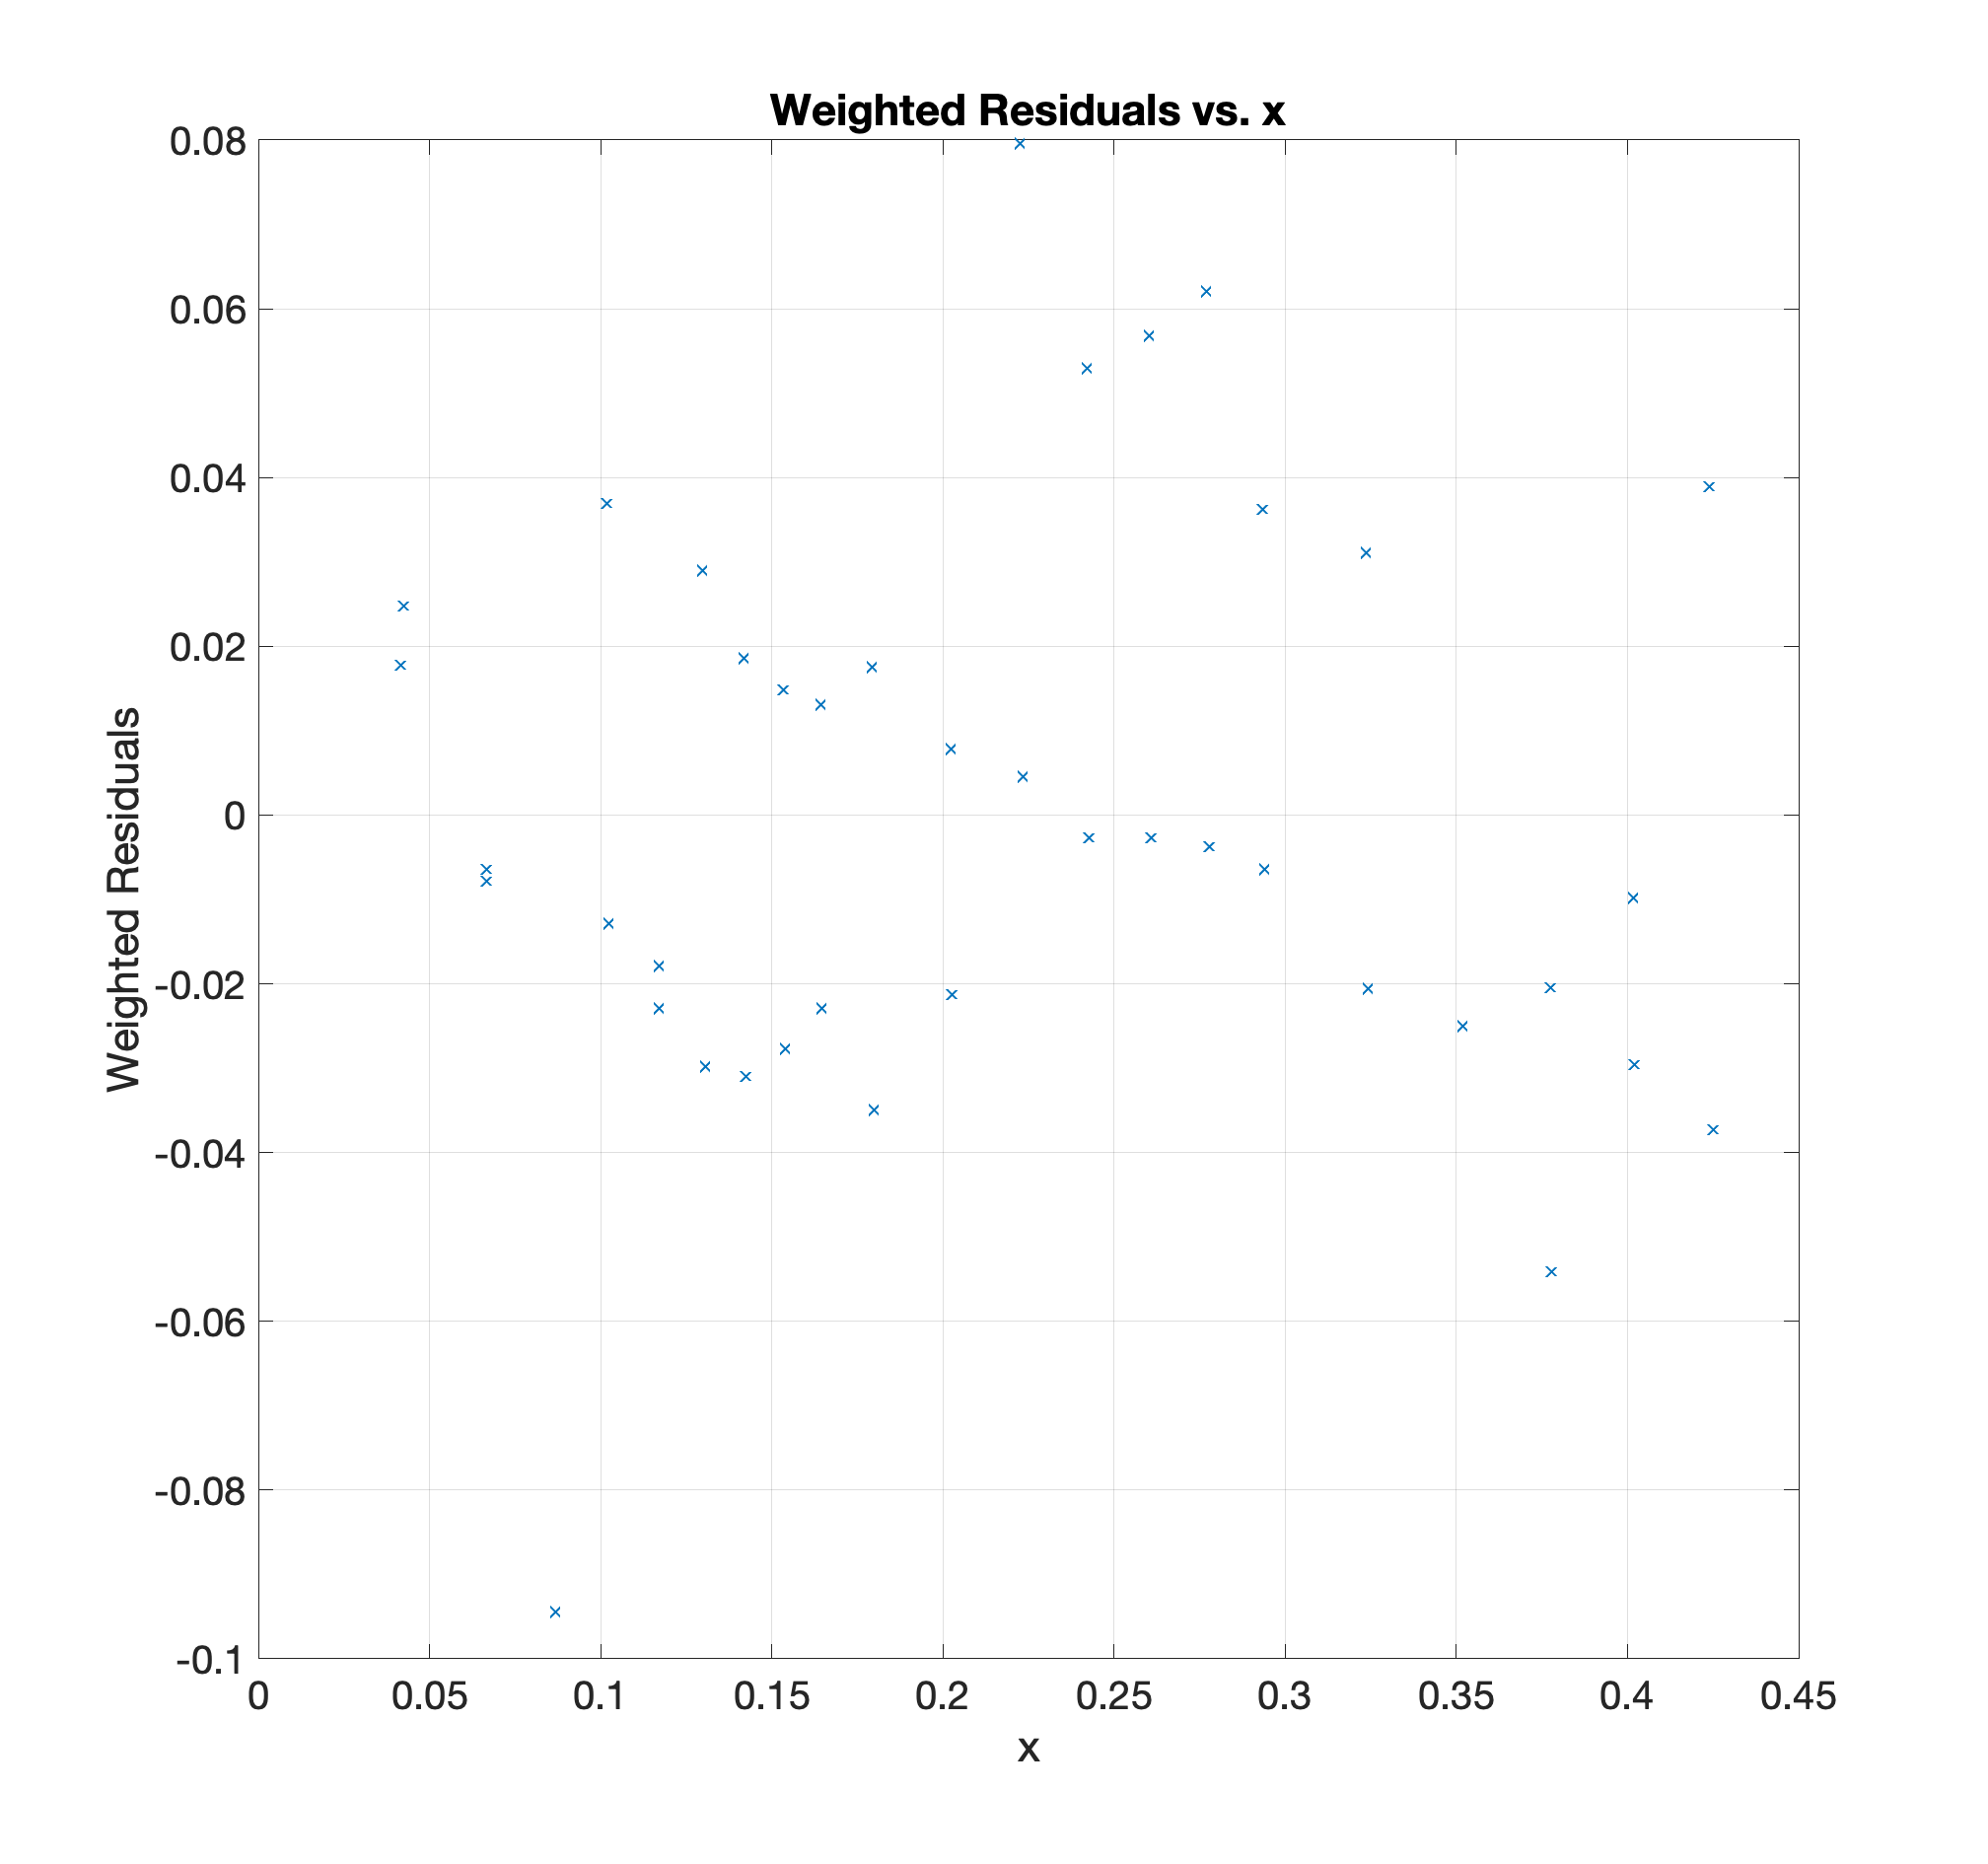


figure(5)
set(gcf,'Units','Normalized','Position',[0.65 0.5 0.3 0.5])
plot(t_inf(1:length(outp.residuals),:), (outp.residuals), 'x')
title('Weighted Residuals vs. x')
xlabel('x')
ylabel('Weighted Residuals')
set(gca,'FontSize',20) 
grid on

fprintf('\n\nBest Value of del is: del = %.5f\n',del_best)



Best Value of del is: del = 0.00155


fprintf('\n\nBest Value of b is: b = %.5f +/- %.5f\n',b,b_err)



Best Value of b is: b = 0.01155 +/- 0.00150


fprintf('Sum of Chi Squared = %.3f \n',gof.sse) 

Sum of Chi Squared = 0.046 


error_matrix = inv(outp.Jacobian'*outp.Jacobian); 
dcov =  diag(error_matrix);;
unc = sqrt(dcov)';

fprintf('Reduced Chi Squared = %.3f \n',gof.sse/gof.dfe)

Reduced Chi Squared = 0.001 


fprintf('Calculated value of g = %.5f +/- %.5f m/s^2 \n',2*fitobj.p1,2*unc(1))

Calculated value of g = 9.83261 +/- 0.37370 m/s^2 


fprintf('Calculated value of V0 = %.5f +/- %.5f m/s \n',fitobj.p2,unc(2))

Calculated value of V0 = 0.29712 +/- 0.04551 m/s 


function chival = getSSE(x,y,sig_y,del)
    [~, gof, ~] = fit(x, y,'poly1', 'Weights',(1./sig_y).^2);
    sprintf(['Chi Squared Fit --- del = %.4f'...
        ' --- SSE = %.0f\n'],del,gof.sse);
    chival = gof.sse;
end

function p = getparams(x,y,sig_y,del)
    [fitobj, gof, outp] = fit(x, y,'poly1', ...
        'Weights',(1./sig_y).^2);
    sprintf(['Chi Squared Fit --- del = %.5f'...
        ' --- SSE = %.0f\n'],del,gof.sse);
    p.b = fitobj.p1;
    p.a = fitobj.p2;
    p.res = outp.residuals;
    p.outp = outp;
    p.fitobj = fitobj;
    error_matrix = inv(outp.Jacobian'*outp.Jacobian); 
    dcov =  diag(error_matrix);
    unc = sqrt(dcov)';
    p.b_err = unc(1);
    p.a_err = unc(2);
    p.r_chi = gof.sse/gof.dfe;
end

function [t_nylon,t_steel,y,y_err] = ...
    drop(delete,t_nylon,t_steel,y,y_err)
    t_nylon(delete,:) = [];
    t_steel(delete,:) = [];
    y(delete,:) = [];
    y_err(delete,:) = [];
end
